clc; clear; close all;

%% Load ECG Data
data = load('RRSYNTHdata.mat');
ecgstr = data.data(1).ekg;

ecg = ecgstr.v(:);
fs  = ecgstr.fs;

t = (0:length(ecg)-1)/fs;
N = length(ecg);

duration = 10; 
idx1 = 1:round(duration * fs);

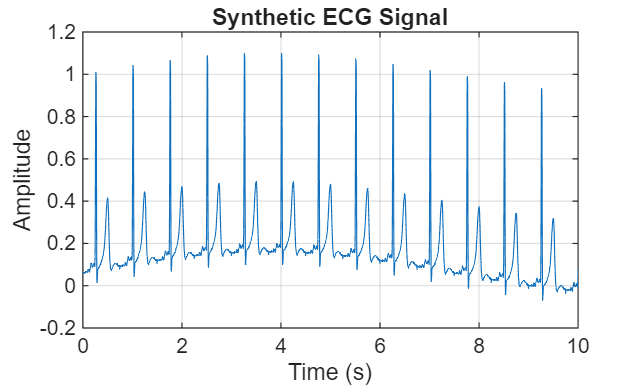


% TIME DOMAIN

figure;
plot(t(idx1), ecg(idx1));
title('Synthetic ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

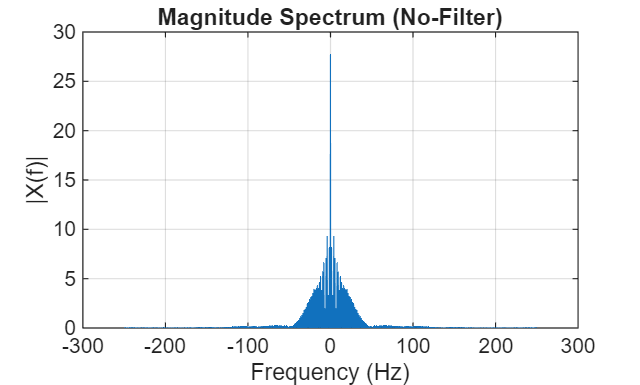


% FFT (RAW - CENTERED)

f = linspace(-fs/2, fs/2, N);
ECG_fft = fft(ecg)/fs;

figure;
plot(f, fftshift(abs(ECG_fft)));
title('Magnitude Spectrum (No-Filter)');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
grid on;

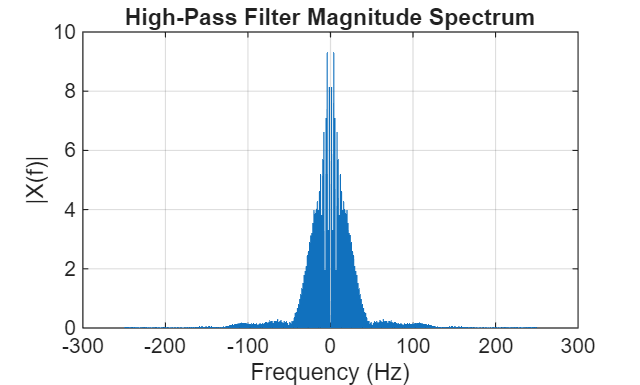

% FILTERING

% HIGHPASS
fc = 0.5;
Wn = fc / (fs/2);

[b_hp, a_hp] = butter(4, Wn, 'high');
ecg_hp = filtfilt(b_hp, a_hp, ecg);

ECGhp_fft = fft(ecg_hp)/fs;

figure;
plot(f, fftshift(abs(ECGhp_fft)));
title('High-Pass Filter Magnitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
grid on;

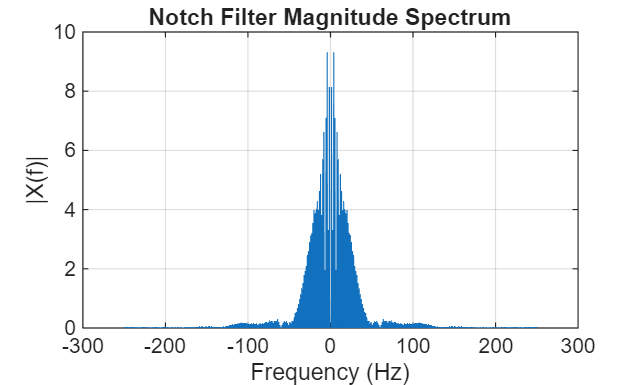


% NOTCH 
d_notch = designfilt('bandstopfir', ...
    'FilterOrder', 500, ...
    'CutoffFrequency1', 59, ...
    'CutoffFrequency2', 61, ...
    'SampleRate', fs);

filteredecg = filtfilt(d_notch, ecg_hp);
Fecg_fft = fft(filteredecg)/fs;

figure;
plot(f, fftshift(abs(Fecg_fft)));
title('Notch Filter Magnitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
grid on;

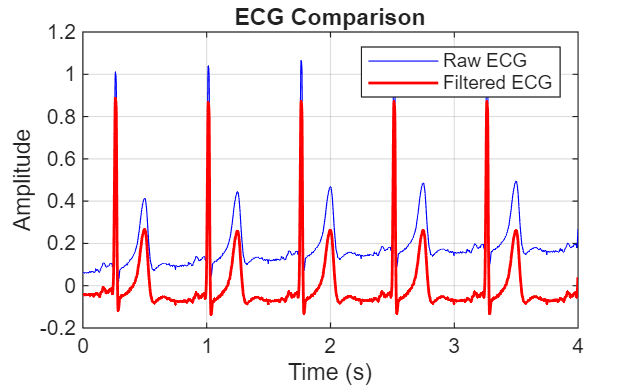

% COMPARISON
idx = 1:min(2000, N);

figure;
plot(t(idx), ecg(idx), 'b'); hold on;
plot(t(idx), filteredecg(idx), 'r', 'LineWidth', 1.2);

legend('Raw ECG','Filtered ECG');
title('ECG Comparison');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

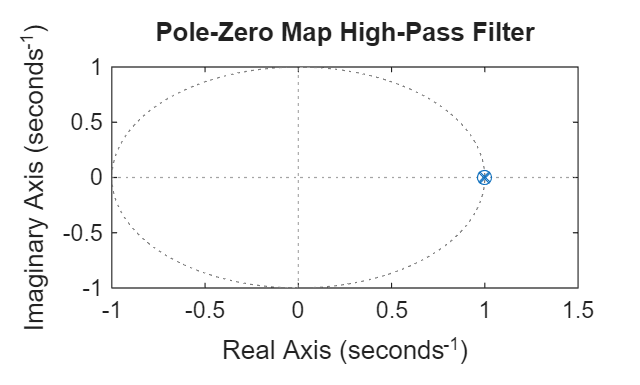

% LAPLACE DOMAIN ANALYSIS

n = 4;
wc = 2*pi*0.5;

[num, den] = butter(n, wc, 'high', 's');
H = tf(num, den);

Hd = c2d(H, 1/fs, 'tustin');

figure;
pzmap(Hd);
title('Pole-Zero Map High-Pass Filter');

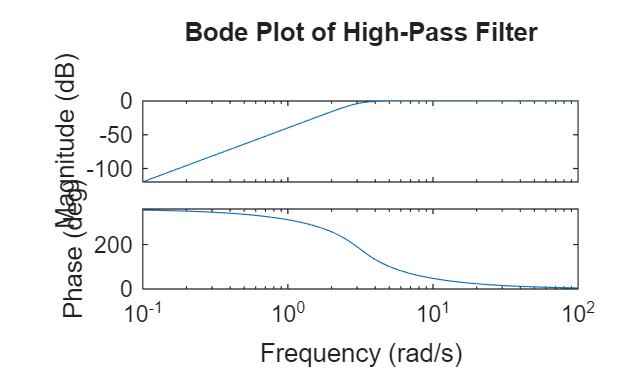


figure;
bode(H);
title('Bode Plot of High-Pass Filter');



[b_n, a_n] = tf(d_notch); 
n

n = 4

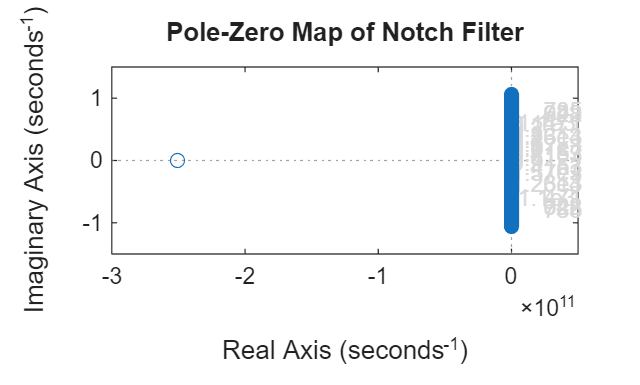

H_notch_d = tf(b_n, a_n, 1/fs);

figure;
pzmap(H_notch_d);
title('Pole-Zero Map of Notch Filter');
grid on;

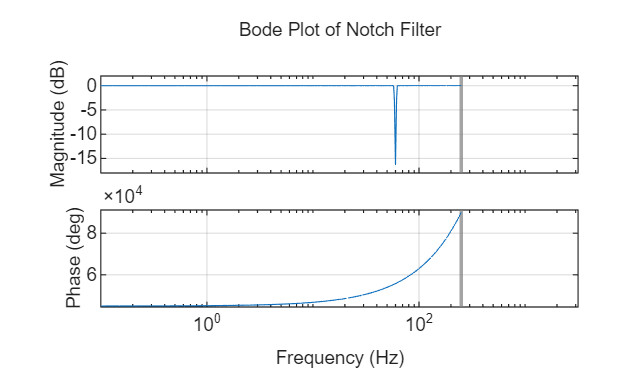


figure;
opts = bodeoptions;
opts.FreqUnits = 'Hz';
bode(H_notch_d, opts);
title('Bode Plot of Notch Filter');
grid on;

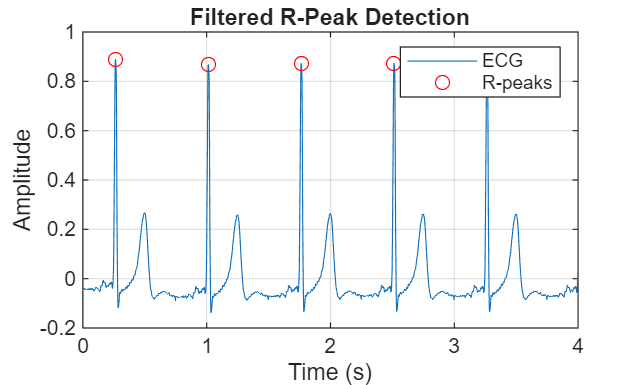

% HEART STATS
signal = filteredecg;

minPeakDist = round(0.6 * fs);

[peaks, locs] = findpeaks(signal,...
    'MinPeakHeight', 0.4*max(signal),...
    'MinPeakDistance', minPeakDist);

idx = 1:min(2000, N);

figure;
plot(t(idx), signal(idx)); hold on;

valid = locs <= idx(end);
plot(t(locs(valid)), peaks(valid), 'ro');

title('Filtered R-Peak Detection');
xlabel('Time (s)');
ylabel('Amplitude');
legend('ECG','R-peaks');
grid on;


RR_intervals = diff(locs) / fs;
HR = 60 ./ RR_intervals;

HR_avg = mean(HR);
fprintf('Average Heart Rate: %.2f bpm\n', HR_avg);

Average Heart Rate: 80.00 bpm


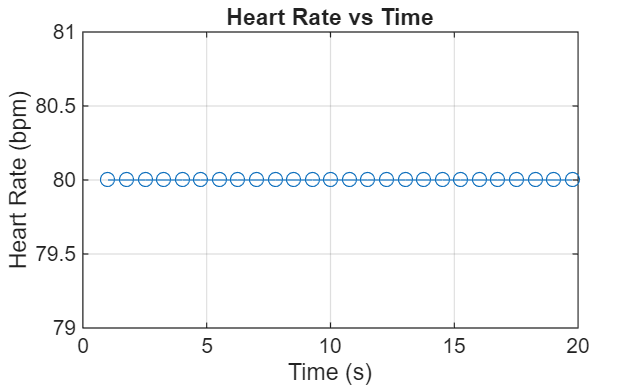


t_rr = t(locs(2:end));

figure;
idx_hr = t_rr <= 20;

plot(t_rr(idx_hr), HR(idx_hr), '-o');
title('Heart Rate vs Time');
xlabel('Time (s)');
ylabel('Heart Rate (bpm)');
grid on;